# **EFTERÅR 2016 RE-EKSAMEN**

***MADS STEINER KRISTENSEN***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');

Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

**En kontinuært stokastisk variabel har følgende tæthedsfunktion (pmf): **


$$f_X \left(x\right)=\left\lbrace \begin{array}{cc}
A\cdot x+B & -2<x\le 3\\
0 & \mathrm{ellers}
\end{array}\right\rbrace$$


## 1.1 GYLDIG TÆTHEDSFUNKTION

For en gyldig tæthedsfunktion gælder, at


$$\int_{-\infty }^{\infty } f_x \left(x\right)\mathrm{dx}=1$$


Hvor der i denne situation derfor gælder, at


$$\int_{-2}^3 f_x \left(x\right)\mathrm{dx}=1=A$$


Det ses på figur 1, at fordelingsfukntionen er en trekant med en ukendt side og arealet af en retvinklet trekant bestemmes som,


$$A=\frac{1}{2}\cdot b\cdot h$$


Hvor b er bredden (5) [-2;3] og h er højden. I dette tilfælde er h den ukendte og løses ved følgende.


$$h=\frac{2\cdot A}{5}$$


A = 1;
b = 5;

h = (2 * A) / b;

disp("For værdien k = " + h + " til fx(-2) er det en gyldighed tæthedsfunktion");

For værdien k = 0.4 til fx(-2) er det en gyldighed tæthedsfunktion


## 1.2 FORDELINGSFUNKTION

 For fordelingsfunktionen gælder, at


$$F_X \left(x\right)=\int_{-\infty }^x f_x \left(x\right)\mathrm{dx}$$


syms A B C x

f = A * x + B;

int(f, x) + C

$$ans = \frac{A\,x^{2}}{2}+B\,x+C$$

Hvilket dermed giver, at 


$$F_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<\left(-2\right)\\
\frac{1}{2}A\cdot x^2 +B\cdot x+C & -2\le x\le 3\\
1 & 3<x
\end{array}\right\rbrack \right\rbrace$$


## 1.3 FORVENTNINGSVÆRDI OG VARIANS

For forvetningsværdien gælder, at


$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}$$


clear x A B

A = (-2/25);
B = 6/25;

f = @(x)  x.* (A .* x + B);

value.expectation = round(integral(f, -2, 3), 10);

disp("Forventningsværdien er bestemt til at være: " + value.expectation);

Forventningsværdien er bestemt til at være: -0.33333


For variansen gælder, at


$$\mathrm{Var}\left(x\right)=\int_{-\infty }^{\infty } \left(x-\bar{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


f = @(x)  (x.^2) .* (A .* x + B);

value.expectationsquared = round(integral(f, -2, 3), 10);

disp("Variansen er bestemt til at være: " + (value.expectationsquared - value.expectation^2));

Variansen er bestemt til at være: 1.3889


## 1.4 SANDSYNLIGHED

For sandsynligheden gælder, at 


$$F_X \left(x\right)=\int_{-\infty }^x f_x \left(x\right)\mathrm{dx}=P\left(X\le x\right)$$


Hvormed der i dette tilfælde anvendes, at 


$$F_X \left(0\right)=\int_{-\infty }^0 f_x \left(0\right)\mathrm{dx}=P\left(X<0\right)$$


Hvortil det er kendt, at


$$F_X \left(0\right)=\frac{1}{2}A\cdot 0^2 +B\cdot 0+C=C$$


A = (-2/25);
B = 6/25;
C = 16/25;

FZero = 1/2 * A * 0^2 + B * 0 + C;

disp("Sandsynligheden er dermed bestemt til at være " + FZero);

Sandsynligheden er dermed bestemt til at være 0.64


# **2 STOKASTISK PROCESS**

**En diskret stokastisk process er givet for den n'te ved**


$$X\left(n\right)=w\left(n\right)+0\ldotp 7$$


**Hvor w(n) er i.i.d fordelte efter den angivet tabel.**

## 2.1 SKITSERING AF SAMPLES

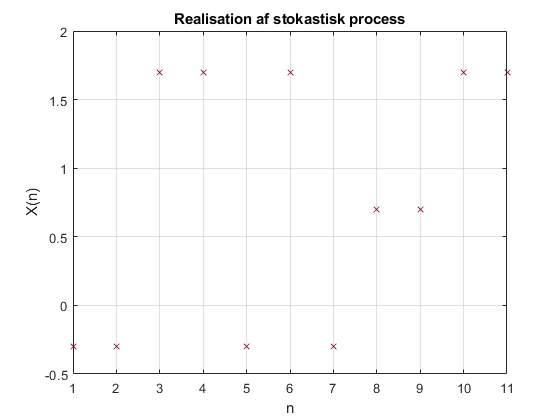

n = 0:10;

realisation = unidrnd(3, 1, 11) - 2 + 0.7;

figure(1)
plot(1:length(realisation), realisation, 'x', 'Color', Color.DeepCleret);
title('Realisation af stokastisk process');
xlabel('n')
ylabel('X(n)')
grid on

## 2.2 MIDDELVÆRDI OG VARIANS


$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)+0\ldotp 7\right\rbrack$$



$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack +0\ldotp 7$$



$$E\left\lbrack w\left(n\right)\right\rbrack =\sum_w w\left(n\right)\cdot f_{w\left(n\right)} \left(w\left(n\right)\right)$$


ExpectationValueW = -1 * (1/3) + 0 * (1/3) + 1 * (1/3);

MeanValue = ExpectationValueW + 0.7;

disp("Ensemble middelværdien er bestemt til at være " + MeanValue);

Ensemble middelværdien er bestemt til at være 0.7


For variansen gælder, at 


$$\sigma_{x\left(n\right)}^2 =E\left\lbrack {X\left(n\right)}^2 \right\rbrack -E{\left\lbrack X\left(n\right)\right\rbrack }^2 =E\left\lbrack {\left(w\left(n\right)+0\ldotp 7\right)}^2 \right\rbrack -E{\left\lbrack w\left(n\right)+0\ldotp 7\right\rbrack }^2$$



$$\sigma_{x\left(n\right)}^2 =E\left\lbrack {w\left(n\right)}^2 \right\rbrack -E{\left\lbrack w\left(n\right)\right\rbrack }^2 =E\left\lbrack {w\left(n\right)}^2 \right\rbrack$$


Variance = (-1)^2 * (1/3) + 0^2 * (1/3) + 1^2 * (1/3);

disp("Ensemble variansen er bestemt til at være " + Variance);

Ensemble variansen er bestemt til at være 0.66667


## 2.3 AUTOKORRELATION

Formlen til at bestemme autokorrelationen for $X\left(n\right)$er som følgende.


$$R_{\mathrm{XX}} \left(\tau \right)=\sum_n x\left(n\right)\cdot x\left(n-\tau \right)\cdot f_x \left(x\right)$$


hvor $f_x \left(x\right)=f_w \left(w+0\ldotp 7\right)$.

## 2.4 PROCESSEN

Processen er wss da middelværdien og autokorrelationen ikke er tidsafhængige. Processen er ergodisk da pmf kan bestemmes ud fra en realisation.

# **3 SANDSYNLIGHED**

**I et tognet angives forsinkelser til at kunne skyldes blade på skinnerne, signalfejl eller personalemangel. Hændelserne er uafhængige og er ikke disjunkte. Hvis der opstår en forsinkelse, vil der være blade på skinnerne 1/4 af gangene, der vil være signalfejl 1/2 af gangene, og der vil være personalemangel 1/4 af gangene.**

## 3.1 VENN DIAGRAM

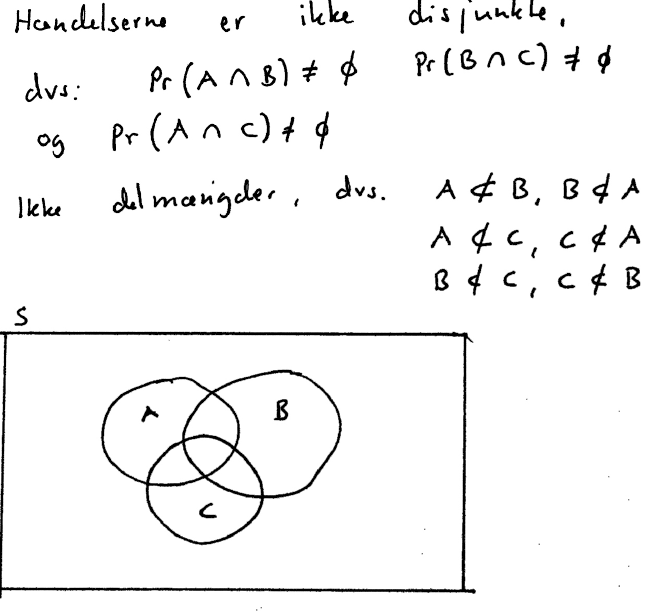

## 3.2 BLADE OG SIGNALFEJL

Find sandsynligheden for, at der både er blade på skinnerne og signalfejl.


$$P\left(A\cap B\right)=P\left(A|B\right)\cdot P\left(B\right)$$


da begivenhederne er uafhængige ses følgende


$$P\left(A|B\right)=P\left(A\right)$$


hvorved


$$P\left(A\cap B\right)=P\left(A\right)\cdot P\left(B\right)$$


A = 1/4;
B = 1/2;
C = 1/4;

LeavesAndSignal = A * B;

disp("Sandsynligheden for blade på skinnerne og signalfejl er " + LeavesAndSignal);

Sandsynligheden for blade på skinnerne og signalfejl er 0.125


## 3.3 BLADER ELLER SIGNALFEJL

Find sandsynligheden for, at der enten er blade på skinnerne eller signalfejl.


$$P\left(A\cup B\right)=P\left(A\right)+P\left(B\right)-P\left(A\cap B\right)$$


LeavesOrSignal = A + B - LeavesAndSignal;

disp("Sandsynligheden for blade på skinnerne eller signalfejl er " + LeavesOrSignal);

Sandsynligheden for blade på skinnerne eller signalfejl er 0.625


## 3.4 SAMLET SANDSYNLIGHED

Find sandsynligheden for, at en forsinkelse på toget skyldes blade på skinnerne, signalfejl eller personalemangel.


$$P\left(A\cup B\cup C\right)=P\left(A\right)+P\left(B\right)+P\left(C\right)-P\left(A\cap B\right)-P\left(A\cap C\right)-P\left(B\cap C\right)+P\left(A\cap B\cap C\right)$$


da A, B og C er uafhængige gælder, at


$$P\left(A\cup B\cup C\right)=P\left(A\right)+P\left(B\right)+P\left(C\right)-P\left(A\right)\cdot P\left(B\right)-P\left(A\right)\cdot P\left(C\right)-P\left(B\right)\cdot P\left(C\right)+P\left(A\right)\cdot P\left(B\right)\cdot P\left(C\right)$$


LeavesSignalPersonal = A + B + C - (A * B) - (A * C) - (B * C) + (A * B * C);


disp("Sandsynligheden for blade på skinnerne, signalfejl eller personale mangel er " + LeavesSignalPersonal);

Sandsynligheden for blade på skinnerne, signalfejl eller personale mangel er 0.71875


# **4 STATISTISK**

**I et studie af en anerkendt metode til vægttab undersøges 10 patienter før behandling, og ét år efter behandling.**

## 4.1 NULL HYPOTESE

Opstil en null hypotese og alternativ hypotese for at bestemme, om behandlingen har ændret patienternes vægt.

$H_0 :$ forventet vægtændring $\left(\delta \right)=0$

$H_1 :$ forventet vægtændring $\left(\delta \right)\not= 0$

## 4.2 PARRET EL. UPARRET

Testen bør være parret da det drejer sig om samme patient før og efter behandling. Hvert punkt i datasættet er tilsvarende et punkt i det andet datasæt.

## 4.3 MIDDEL FORSKELLEN

Estimering af middeforskellen på patienternes vægt før og efter behandling kan findes som.


$$\delta^ˆ =\overline{d} =\frac{1}{n}\sum_{i=1}^n \left(X_{1i} -X_{2i} \right)$$


WeightBefore = [140, 138, 110, 154, 125, 169, 142, 162, 131, 122];
WeightAfter = [130, 121, 127, 101, 92, 170, 143, 170, 134, 85];

MaximumLikelihood = 1/10 * sum(WeightAfter - WeightBefore);

disp("Estimering af middelforskellen af patienternes vægt før og efter behandling er bestemt til at være " + MaximumLikelihood);

Estimering af middelforskellen af patienternes vægt før og efter behandling er bestemt til at være -12


## 4.4 VARIANS

Sample variansen kan findes som 


$$s_d^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(d_i -\overline{d} \right)}^2 =\frac{1}{n-1}\sum_{i=1}^n {\left(X_{1i} -X_{2i} -\overline{d} \right)}^2$$


SampleVariance = (1/(10-1)) * sum(((WeightAfter - WeightBefore) - MaximumLikelihood).^2);

## 4.5 T-TEST

Anvendt en parret t-test til hypotesetest. Kan null hypotesen afvises med et signifikansniveau på 0.05?


$$t=\frac{\overline{d} -\delta }{\frac{s_d }{\sqrt{n}}}=\frac{\overline{d} -\delta }{\frac{\sqrt{s_d^2 }}{\sqrt{n}}}$$



$$\mathrm{pvalue}=2\cdot \left(1-t_{\mathrm{cdf}} \left(|t|,n-1\right)\right)$$


t = (MaximumLikelihood - 0) / (sqrt(SampleVariance) / sqrt(10));

pValue = 2 * (1 - tcdf(abs(t), 10-1));

if pValue > 0.05
    disp("Da p-værdien: " + pValue + " er større end 0.05 kan null hypotesen ikke afvises");
else
    disp("Da p-værdien: " + pValue + " er større end 0.05 kan null hypotesen afvises");
end

Da p-værdien: 0.12683 er større end 0.05 kan null hypotesen ikke afvises


## 4.6 KONFIDENSINTERVAL

For at bestemmes konfidensintervallet anvendes, at


$$\delta_{\pm } =\overline{d} \pm t_0 \cdot \frac{s_d }{\sqrt{n}}$$


TNull = tinv(0.975, 10 -1);

ConfidenceInterval.Plus = MaximumLikelihood + TNull * (sqrt(SampleVariance)/sqrt(10));

ConfidenceInterval.Minus = MaximumLikelihood - TNull * (sqrt(SampleVariance)/sqrt(10));

disp("Konfidensintervallet for vægtforskellen før og efter behandlingen er: " + ConfidenceInterval.Minus + ", " + ConfidenceInterval.Plus);

Konfidensintervallet for vægtforskellen før og efter behandlingen er: -28.1374, 4.1374
